# Allées de tourbillons de von Karman

clear all
close all
clc

Il y a 12 configurations testées. On commence par charger les paramètres: vitesse de l'écoulement $V$ et diamètre de l'obstacle $D$, fréquence d'acquisition du signal $F_s$ et viscosité cinématique de l'air $\nu$. On charge ensuite les signaux enregistrés: chaque ligne de la matrice data correspond au signal de vitesse enregistré pour une configuration donnée.

load('parameters.mat')
load('dataset.mat')

### Exo1-Analyse de premier signal

On choisit la première mesure et l'on trace tout d'abord le signal de vitesse en fonction du temps.

indexRun=1;

disp(['Results for D=',num2str(D(indexRun)*1000), ' mm and V=',num2str(V(indexRun)),' m/s.'])

Results for D=12.8 mm and V=3.45 m/s.


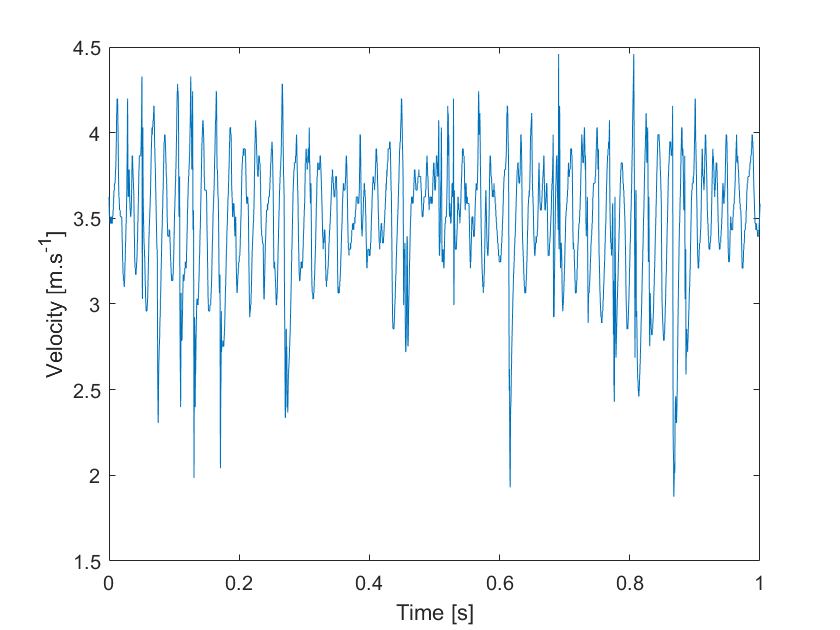

U=data(indexRun,:);
Ns=length(U);
t=(0:(Ns-1))/Fs;


figure;
plot(t,U)
xlabel('Time [s]')
ylabel('Velocity [m.s^{-1}]')
xlim([0,1])

On trace maintenant le spectre du signal basé sur une estimation de la densité spectrale de puissance du signal par la méthode de Welch. A chaque valeur de fréquence en abscisse, le spectre associe en ordonnée une valeur correspondant à la puissance du signal autour de cette fréquence.

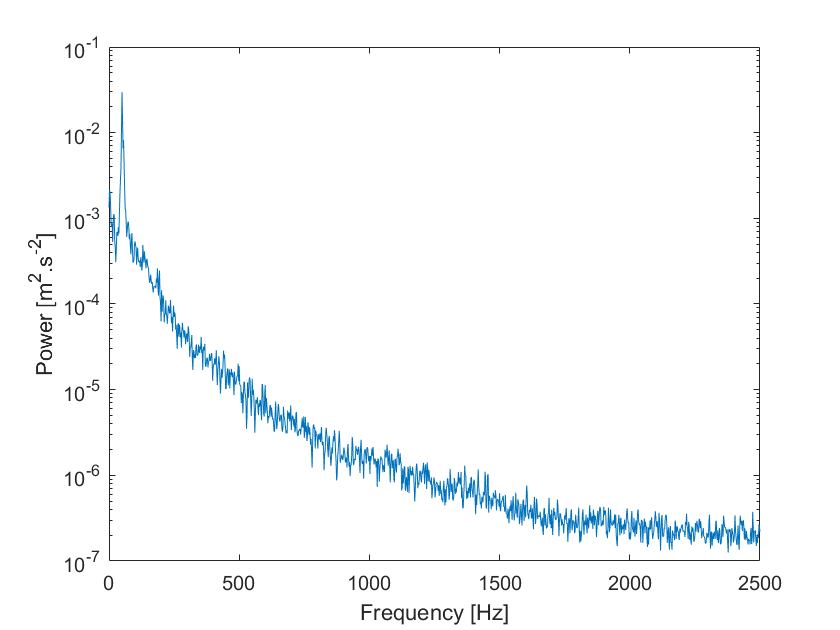

window=hamming(round(Fs/2));
noverlap=round(length(window)/2);
nfft=length(window);
[Pxx,f]=pwelch(U-mean(U),window,noverlap,nfft,Fs,'power');

figure;
semilogy(f,Pxx)
xlabel('Frequency [Hz]')
ylabel('Power [m^2.s^{-2}]')

[sss,p]=max(Pxx)

sss = 0.0297

p = 26

f(p)

ans = 50

### Exo3 Nombre sans dimension

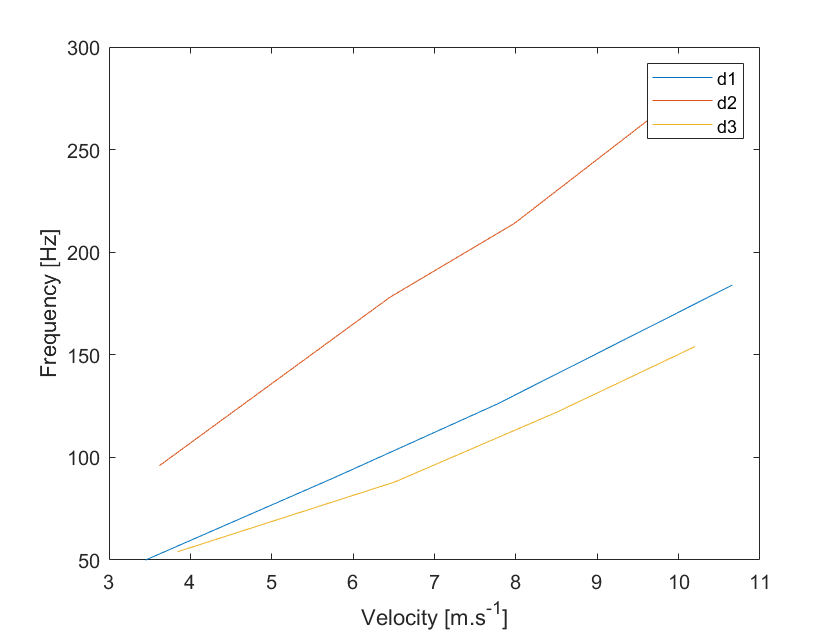

figure;
fmax = zeros(1,12);
for i=1:12
  U=data(i,:);
  Ns=length(U);
  t=(0:(Ns-1))/Fs; 
  
  window=hamming(round(Fs/2));
  noverlap=round(length(window)/2);
  nfft=length(window);
  [Pxx,f]=pwelch(U-mean(U),window,noverlap,nfft,Fs,'power');
  
  [Pmax, pmax] = max(Pxx(1:500));
  fmax(i) = f(pmax);
end
d1 = D(1);
f1 = fmax(1:4);
v1 = V(1:4);

d2 = D(5);
f2 = fmax(5:8);
v2 = V(5:8);

d3 = D(9);
f3 = fmax(9:12);
v3 = V(9:12);

figure
plot(v1, f1)
hold on
plot(v2, f2)
plot(v3, f3)
xlabel('Velocity [m.s^{-1}]')
ylabel('Frequency [Hz]')
legend('d1', 'd2', 'd3')

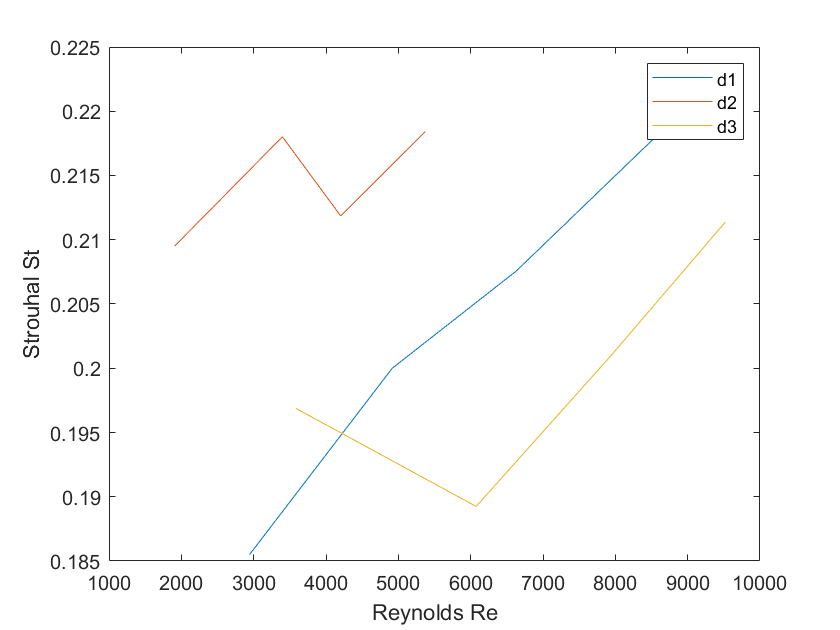


St1 = f1*d1./v1;
St2 = f2*d2./v2;
St3 = f3*d3./v3;

Re1 = v1*d1/nu_air;
Re2 = v2*d2/nu_air;
Re3 = v3*d3/nu_air;

figure(2)
plot(Re1, St1)
hold on
plot(Re2, St2)
plot(Re3, St3)
xlabel('Reynolds Re')
ylabel('Strouhal St')
legend('d1', 'd2', 'd3')